# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 노예훈        **

**학번**** : 201614627 **

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

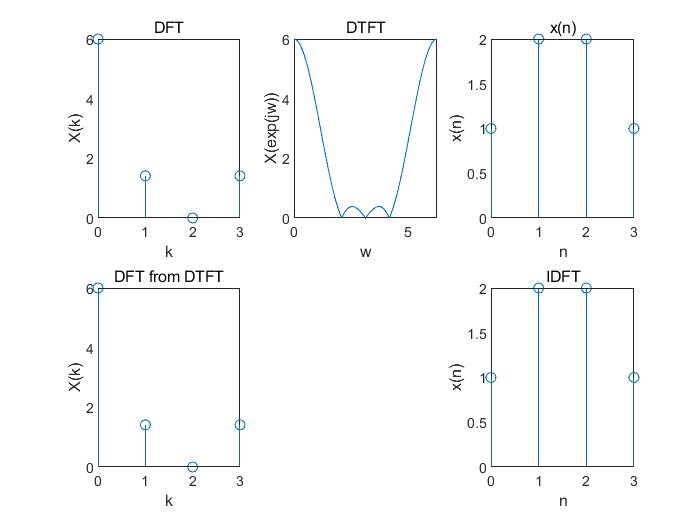

xn = [1 2 2 1];
n= 0 : 3;
k= 0 : 3;
N = length(k);
Xk = dft(xn, N);
xni = idft(Xk, N);

w = [0:500]*2*pi/500;
kw = (2*pi.*k)./N;

Xw = 1 + 2*exp(-1j*w) + 2*exp(-2*1j*w) + exp(-3*1j*w);

Xwk = 1 + 2*exp(-1j*kw) + 2*exp(-2*1j*kw) + exp(-3*1j*kw);

figure(1)
subplot(2,3,1), stem(k, abs(Xk));
title('DFT');
xlabel('k');
ylabel('X(k)');

subplot(2,3,2), plot(w, abs(Xw));
title('DTFT');
xlabel('w');
ylabel('X(exp(jw))');
axis([0 2*pi 0 6]);

subplot(2,3,4), stem(k, abs(Xwk));
title('DFT from DTFT');
xlabel('k');
ylabel('X(k)');

subplot(2,3,6), stem(n, (abs(xni)));
title('IDFT');
xlabel('n');
ylabel('x(n)');

subplot(2,3,3), stem(n, xn);
title('x(n)');
xlabel('n');
ylabel('x(n)');

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

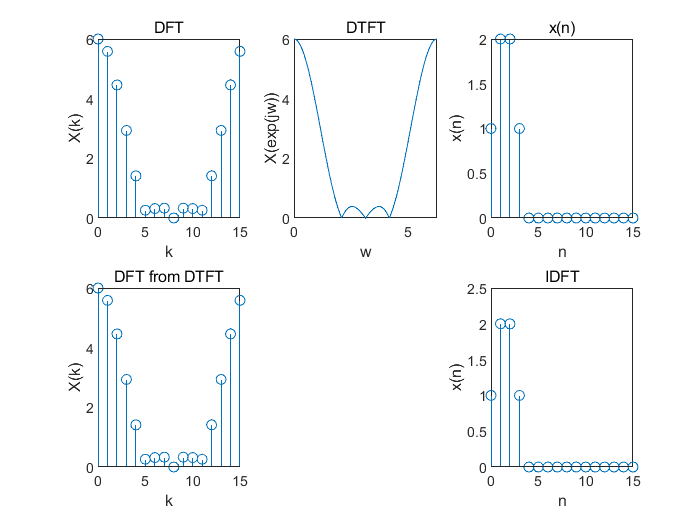

xn = [1 2 2 1 0 0 0 0 0 0 0 0 0 0 0 0];
n= 0 : 15;
k= 0 : 15;
N = length(k);
Xk = dft(xn, N);
xni = idft(Xk, N);


w = [0:500]*2*pi/500;
kw = (2*pi.*k)./N;

Xw = 1 + 2*exp(-1j*w) + 2*exp(-2*1j*w) + exp(-3*1j*w);

Xwk = 1 + 2*exp(-1j*kw) + 2*exp(-2*1j*kw) + exp(-3*1j*kw);

figure(2)
subplot(2,3,1), stem(k, abs(Xk));
title('DFT');
xlabel('k');
ylabel('X(k)');

subplot(2,3,2), plot(w, abs(Xw));
title('DTFT');
xlabel('w');
ylabel('X(exp(jw))');
axis([0 2*pi 0 6]);

subplot(2,3,4), stem(k, abs(Xwk));
title('DFT from DTFT');
xlabel('k');
ylabel('X(k)');

subplot(2,3,6), stem(n, (abs(xni)));
title('IDFT');
xlabel('n');
ylabel('x(n)');

subplot(2,3,3), stem(n, xn);
title('x(n)');
xlabel('n');
ylabel('x(n)');

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

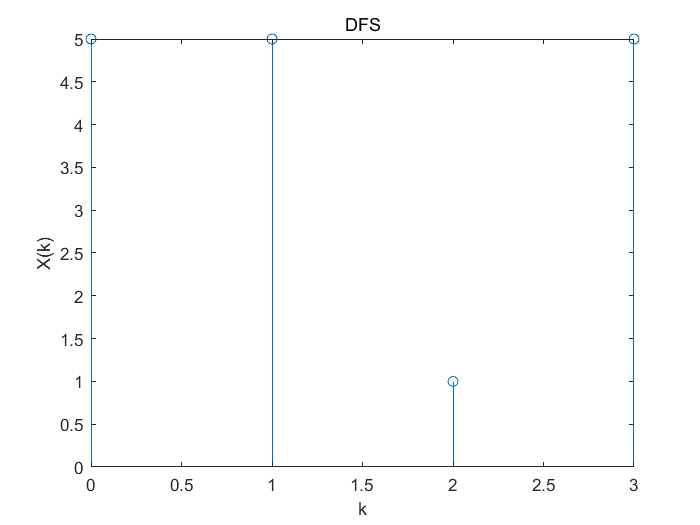

xn = [4 1 -1 1];
k = 0 : 3;
N = length(k);
Xk = dft(xn, N);

figure(3), stem(k, abs(Xk));
title('DFS');
xlabel('k');
ylabel('X(k)');

2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

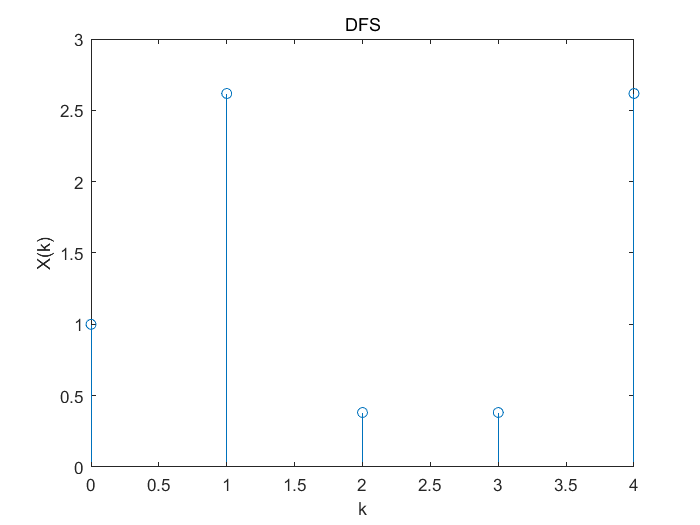

xn = [1 0 -1 -1 0];
k = 0 : 4;
N = length(k);
Xk = dft(xn, N);

figure(4), stem(k, abs(Xk));
title('DFS');
xlabel('k');
ylabel('X(k)');

3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

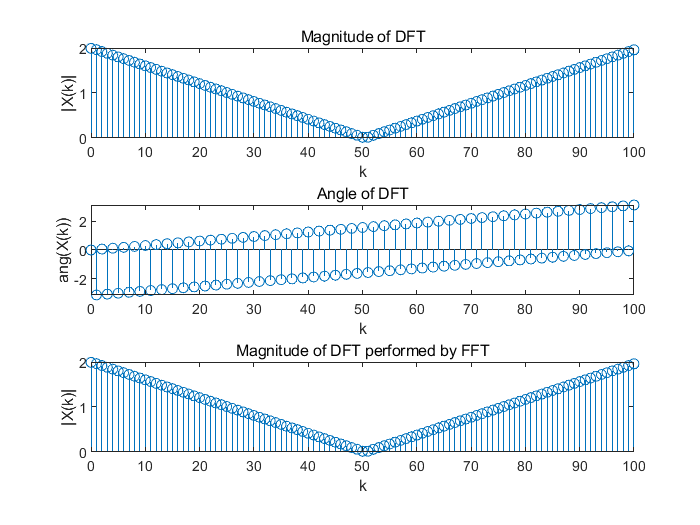

n = 0:100;
xn = sinc((n-50)/2).*sinc((n-50)/2);
k = 0 : 100;
N = length(k);
Xk = dft(xn, N);

FFTxn = fft(xn);

figure(5)
subplot(3,1,1), stem(k, abs(Xk));
title('Magnitude of DFT');
xlabel('k');
ylabel('|X(k)|');

subplot(3,1,2), stem(k, angle(Xk));
title('Angle of DFT');
xlabel('k');
ylabel('ang(X(k))');

subplot(3,1,3), stem(k, abs(FFTxn));
title('Magnitude of DFT performed by FFT');
xlabel('k');
ylabel('|X(k)|');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

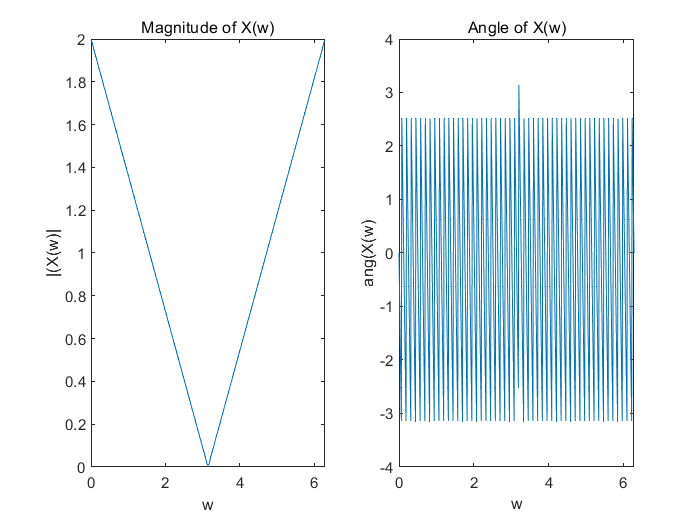

n = 0:100;
xn = sinc((n-50)/2).*sinc((n-50)/2);

kw = 0:500;
w = [0:500]*2*pi/500;
Xw = xn * (exp(-1j*2*pi/500)) .^ (n'*kw);

figure(6)
subplot(1,2,1), plot(w, abs(Xw));
title('Magnitude of X(w)');
xlabel('w');
ylabel('|(X(w)|');

subplot(1,2,2), plot(w, angle(Xw));
title('Angle of X(w)');
xlabel('w');
ylabel('ang(X(w)');

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

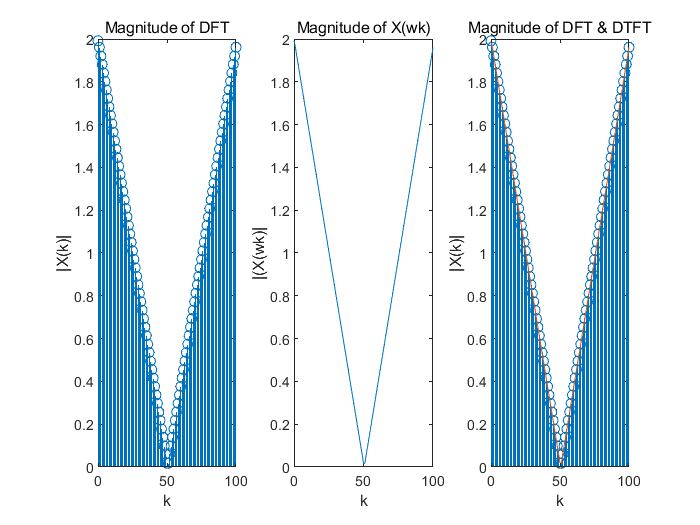

n = 0:100;
xn = sinc((n-50)/2).*sinc((n-50)/2);
k = 0 : 100;
N = length(k);
Xk = dft(xn, N);

Wk = (2*pi./N)*k;

Xwk = xn * (exp(-1j*Wk'.*n)); 

figure(7)
subplot(1,3,1), stem(k, abs(Xk));
title('Magnitude of DFT');
xlabel('k');
ylabel('|X(k)|');

subplot(1,3,2), plot(k, abs(Xwk));
title('Magnitude of X(wk)');
xlabel('k');
ylabel('|(X(wk)|');

subplot(1,3,3), stem(k, abs(Xk)); % DTFT와 DFT의 x axis가 서로 다르기에 w=(2pi/100)K로 대입하여 계산
hold on;
plot(k, abs(Xwk));
hold off;
title('Magnitude of DFT & DTFT');
xlabel('k');
ylabel('|X(k)|');

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

% 복원이 가능하다.
n = 0:100;

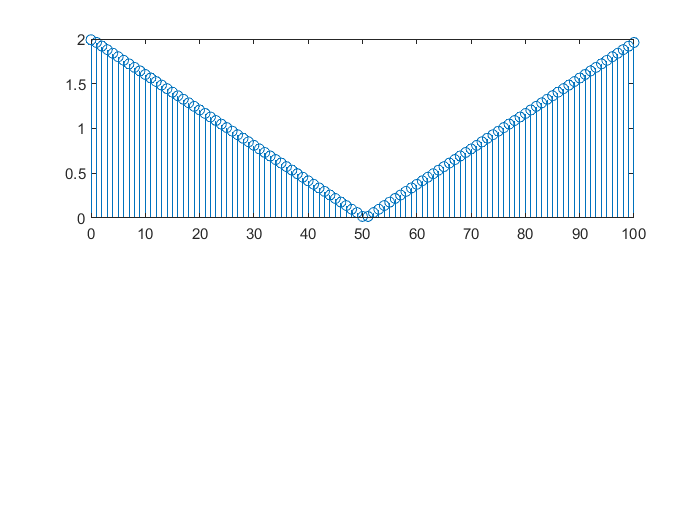

xn = sinc((n-50)/2).*sinc((n-50)/2);

k = 0:100;
N = length(k);

Xk = dft(xn, N);

w = [0:500]*2*pi/500;  

%Wk = (2*pi/N)*k;

%fd = N*(1-exp(1j*Wk).*exp(-1j*w));  % 보간 공식의 분모 항

%fn = -exp(-1j*N*w);                 % 보간 공식의 분자 일부 항

%Xr = (Xk/fd').*fn;                  % 보간 공식 

Xr = Xk .* O;

O = sin(N*w/2)/(N*sin(w/2-pi*k/N))

figure(8)
subplot(2,1,1),stem(k, abs(Xk));



subplot(2,1,2), plot(w, Xr);







function [Xk] = dft(xn, N)
n = [0 : 1: N-1];
k = [0 : 1: N-1];
WN = exp(-1j*2*pi/N);
nk = n'*k;
WKnk = WN .^nk;
Xk = xn * WKnk;
end

function [xn] = idft(Xk, N)
n = [0 : 1: N-1];
k = [0 : 1: N-1];
WN = exp(1j*2*pi/N);
nk = n'*k;
WKnk = WN .^nk;
xn = (Xk * WKnk)/N;
end